close all 
%FEEDBACK CONTROLS PROJECT 
%Adam Chung 
%12/02/2020

%INIT
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
robot = importrobot("ROM_bot.urdf") %Create rigidBodyTree obj

robot =   rigidBodyTree with properties:

     NumBodies: 2
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'lever_arm'  'handle'}
      BaseName: 'base_link'
       Gravity: [0 0 0]
    DataFormat: 'struct'


robot.Gravity = [0 0 -9.81]; 
iviz = interactiveRigidBodyTree(robot,"MarkerBodyName","handle"); %Sim enviroment
ax = gca;
plane = collisionBox(0,0,0.025); %Floor init
plane.Pose = trvec2tform([0.25 0 -0.055]); %Floor pose
show(plane,'Parent', ax);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%Define Trajectory and Input Parameters 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
ROM = -pi/6; 
desired_velocity = 0.5; 
reps = 2; 

rep = [0 ROM] %1 Rep  

rep =          0   -0.5236


q_waypts = []; 

%Populate waypoints 
for i = 1:reps
    q_waypts = [q_waypts rep]; 
end
q_waypts = [q_waypts 0]; 
vels = desired_velocity; 

vels = 0.5000

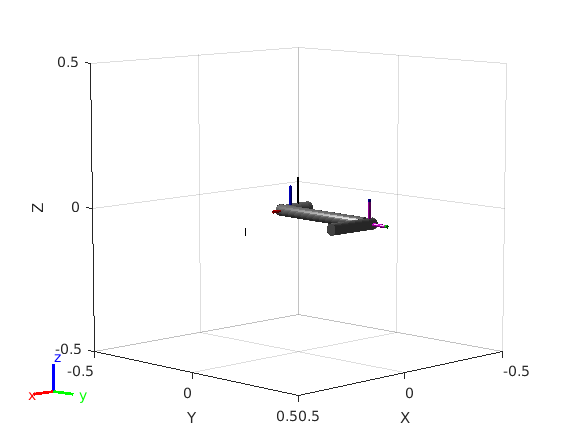

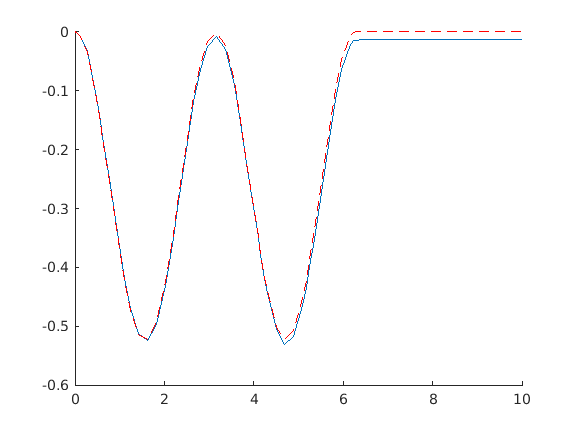




%Simulate desired trajectories with controllers and choose which one to show
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
simout_CPM = sim('CPM.slx');
%simout_PD = sim('PD.slx'); 

%controller = 1 ==> Computed Torque Control
%controller = 2 ==> PD Control 

controller = 1; 
switch controller 
    case 1 
        % Visualize the motion using the interactiveRigidBodyTree
        iviz.ShowMarker = false;
        iviz.showFigure;
        rateCtrlObj = rateControl(length(simout_CPM.tout)/(max(simout_CPM.tout)));
        for i = 1:length(simout_CPM.tout)
            iviz.Configuration = simout_CPM.yout{1}.Values.Data(i,:);
            waitfor(rateCtrlObj);
        end
        q = simout_CPM.q_cpm; 
        q_desired = simout_CPM.q_desired; 
        figure(3)
        hold on 
        plot(q)
        plot(q_desired,'--r')
        hold off
    case 2
        % Visualize the motion using the interactiveRigidBodyTree
        iviz.ShowMarker = false;
        iviz.showFigure;
        rateCtrlObj = rateControl(length(simout_PD.tout)/(max(simout_PD.tout)));
        for i = 1:length(simout_PD.tout)
            iviz.Configuration = simout_PD.yout{1}.Values.Data(i,:);
            waitfor(rateCtrlObj);
        end  
        q = simout_PD.q_pd; 
        q_desired = simout_PD.q_desired; 
        figure(3)
        hold on 
        plot(q)
        plot(q_desired,'--r')
        hold off
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%